# Note 5: Nonlinear DDM

clear; clc

## **Nonlinear Domain Decomposition **

There are 2 main ways to use domain decomposition for nonliear PDEs. One way is to use directly use the domain decomposition techniques on a non-linear problem. In this approach, local nonlinear problems are solved in parallel for each iteration and dirichlet data is exchanged. The other way is to use Newton's method on the global problem. Newton's method involves solving a linear system at each iteration. That linear system can be solved using a Krylov method with a Schwarz preconditioner. These class of methods are called Newton-Krylov-Schwarz (NKS). 

## Newton's Method on a Nonlinear PDE

Let's start with the easist case: Suppose we discretize the 1D PDE 


$$\left\lbrace \begin{array}{ll}
\ddot{u} \left(x\right)-\kappa \left(x\right){\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0 & a<x<b\\
u\left(x\right)=g_a  & x=a\\
u\left(x\right)=g_b  & x=b
\end{array}\right.$$


and we get the root finding problem $f\left(u\right)=0$ where $f:R^n \to R$ is nonlinear. To solve the problem, we use the regular Newton's method on the global (original) problem. 

The algorithm is: iterate until convergence $\ell =0,1,2,\ldotp \ldotp \ldotp$

  
$$\;\textrm{let}\;u^{\ell +1} =u^{\ell \;} +s^{\ell \;} ,\textrm{where}\;s^{\ell \;} \;\textrm{solves}\;\textrm{the}\;\textrm{linear}\;\textrm{system}\;$$


   
$$J\left(u^{\ell \;} \right)\;s^{\ell \;} =-f\left(u^{\ell \;} \right),\textrm{where}\;J\left(u\right)\;\textrm{is}\;\textrm{the}\;\textrm{Jacobian}$$


Our formula for $f\left(u_i \right)$ for an interior node $x_i$ is 

    
$$f\left(u_i \right)=\frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-\kappa \left(x_i \right){\left(1+{\max \left(\frac{u_i -u_{i-1} }{h},-\frac{u_{i+1} -u_i }{\;h},0\right)}^2 \right)}^{\frac{3}{2}}$$


a = 0;  b = 1;      % domain
kap = 1;            % curvature
ga = 0;             % u(a) = ga
gb = 1;             % u(b) = gb
u_exact =@(x) -sqrt(1-x.^2)+1; % exact viscosity solution

We will use the simple problem $a=0,b=1$with BC $u\left(0\right)=0,\;$$u\left(1\right)=1$ and $\kappa =1$.

#### Using Fsolve

Below, we compute a solution with $N$ points using MATLAB's fsolve. The use of fsolve does not require a Jacobian but you wouldn't be able to use domain decomposition on it. 

N = 100;
h = (b-a)/(N+1);
X = a+h:h:b-h;
U = zeros(size(X));
f =@(u) makeF(u,ga,gb,h,kap); % the LHS of the PDE
U = fsolve(f,U); % use nonlinear solver from optimization toolbox


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


#### Using Newton's Method

For the regular Newton's method, you do need to know the Jacobian, or at least some approximation of it. 

For this problem, the Jacobian is given by 

    
$${\left(J\right)}_{\textrm{ij}} =\frac{\partial }{\partial \;u_j }\;f\left(u_i \right)=\left\lbrace \begin{array}{ll}
-\frac{2}{h^2 }-\frac{3}{h^2 }\kappa \;\left(x_i \right)\left(\max \left(u_i -u_{i-1} ,{-u}_{i+1} +u_i ,0\right)\right){\left(1+\max \left(u_i -u_{i-1} ,{-u}_{i+1} +u_i ,0\right)\right)}^{\frac{1}{2}}  & ,i=j\\
\frac{1}{h^2 } & ,\left|i-j\right|=1\\
0 & ,\left|i-j\right|>1
\end{array}\right.$$
 

Therefore, the Jacobian matrix is just a tridiagonal matrix which is inexpensive to solve. Unfortunately, the 

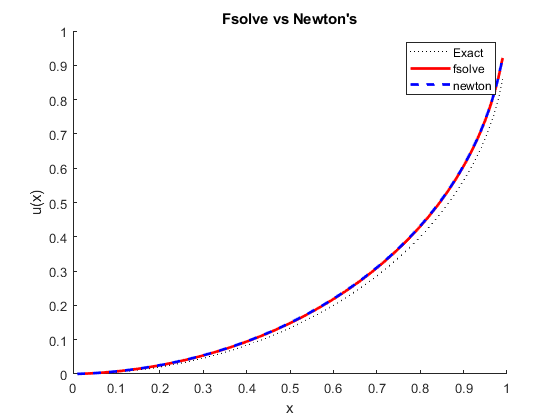

N_iter = 300;
U_newton = zeros(N,N_iter+1);

for l = 1:N_iter
    J = makeJ(U_newton(:,l),ga,gb,h,kap); % construct the Jacobian
    
    b = -makeF(U_newton(:,l),ga,gb,h,kap); % make the rhs
    
    s = J\b; % solve J(u)*s = -f(u)
    
    U_newton(:,l+1) = U_newton(:,l) + s; % new = old + correction
    
    if (norm(b) < 1e-3)
        break
    end
end

figure
hold on
plot(X,u_exact(X),'k:')
plot(X,U,'r','LineWidth',2)
plot(X,U_newton(:,end),'b--','LineWidth',2)
xlabel('x'), ylabel('u(x)')
legend('Exact','fsolve','newton')
title("Fsolve vs Newton's")

The plot above shows the comparison of the fsolve solution and the barebones Newton's method. The convergence of Newton's method is pretty slow. The system has $N=100$ unknowns. You need $N_{\textrm{iter}} =300$ iterations just to get a decent approximation. 

## Domain Decomposition Indexing 

We want to do overlapping domain decomposition in 1D. We will do 2 subdomains. We let $N$ be the total number of unique mesh nodes. For odd $N$, the center node is $c=\frac{N+1}{2}$.We choose an integer overlap parameter $\delta >0$ to control how many interior nodes each domain extend over the center node. We form 2 seperate independent systems for each domain by doubling the degree of freedom for shared nodes. That is each local system will have a system of size $N_{\textrm{loc}} =c+\delta -1$. 

N = 101;
h = 1/(N+1);
c = (N+1)/2;
delta = 2;
Nloc = c+delta-1;
x = h:h:1-h;

## ODDM applied to Newton's Method

For each Newton iteration $\ell =1,2,\ldotp \ldotp \ldotp$, we need to solve 

    $J\left(u^{\ell \;} \right)\;s^{\ell \;} =-f\left(u^{\ell \;} \right)$.

We will ODDM-preconditioned orthodir to solve the systems. See Note 4 for details about this method. 

To implement this method, we need to construct local systems $J_1 \;s_1 =-f_1$ and $J_2 \;s_2 =-f_2$ at every iteration depending on the input $u^{\ell \;}$.

We also need a projection operator which maps the boundary conditions in the DDM. 

N_iter = 150

N_iter = 150

U_newton= zeros(N,1);

for l = 1:N_iter
    
    % construct DDM jacobian system
    [J1,J2] = makeJs(U_newton,ga,gb,h,kap,delta); % should be parallel
    
    [b1,b2] = makeRHS(U_newton,ga,gb,h,kap,delta); % should be parallel 
    
    % use orthodir to compute local solutions of s 
    [s1,s2,conv_iter] = run_orthodir(20,1e-8,Nloc,delta,h,J1,J2,b1,b2);
    conv_iter
    
    % piece together s1 and s2 to make s 
    s = combine(s1,s2,N,delta);
    
    % update newton iteration
    U_newton = U_newton + s;
end

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 3

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 3

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 3

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 3

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

conv_iter = 4

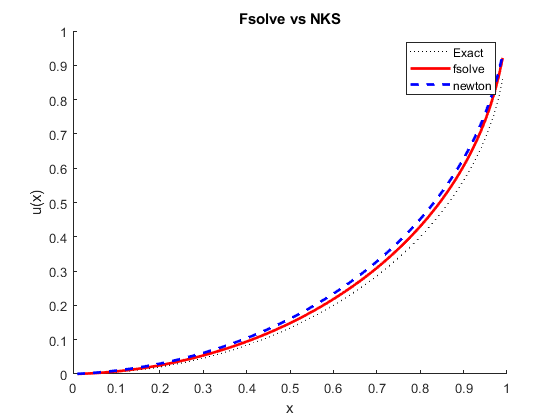


figure
hold on
plot(X,u_exact(X),'k:')
plot(X,U,'r','LineWidth',2)
plot(x,U_newton,'b--','LineWidth',2)
xlabel('x'), ylabel('u(x)')
legend('Exact','fsolve','newton')
title("Fsolve vs NKS")

function J = makeJ(u,ga,gb,h,kap)  % jacobian
n = length(u);

% make tridiagonal and fill the off-diagonals 
J = gallery('tridiag',n,1/h^2,0,1/h^2); 

% this loop is used to fill the diagonal entries 
for i = 1:n
    if (i==1)
        mm = max([u(i)-ga, -u(i+1)+u(i), 0]);
    elseif(i==n)
        mm = max([u(i)-u(i-1),-gb+u(i), 0]);
    else
        mm = max([u(i)-u(i-1),-u(i+1)+u(i), 0]);
    end
    J(i,i) = -2/h^2 - 3/h^2*kap*(1+1/h^2*mm^2)^(1/2)*mm;
end
end


function F = makeF(u,ga,gb,h,kap) % system to find root of
N = length(u);
F = zeros(N,1);
ih2 = 1/h^2;

F(1) = ih2*(u(2)-2*u(1)+ga)-kap*(1+ih2*max([u(1)-ga,u(1)-u(2),0])^2)^(3/2); % at the left endpoint

for j = 2:N-1
    F(j) = ih2*(u(j+1)-2*u(j)+u(j-1))-kap*(1+ih2*max([u(j)-u(j-1),u(j)-u(j+1),0])^2)^(3/2); % at the middle points
end

F(N) = ih2*(gb-2*u(N)+u(N-1))-kap*(1+ih2*max([u(N)-u(N-1),u(N)-gb,0])^2)^(3/2); % at the right endpoint
end

#### For the NKS

In each Newton iteration we want to solve $J\;s=-f$ to which we apply ODDM to get the iterative system

     $\left\lbrack \begin{array}{cc}
J_1  & 0\\
0 & J_2 
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack }^{\left(m+1\right)} =\left\lbrack \begin{array}{c}
-f_1 \\
-f_2 
\end{array}\right\rbrack +{\left\lbrack \begin{array}{c}
g_{12} \\
g_{21} 
\end{array}\right\rbrack }^{\left(m\right)}$.

The subroutine `makeRHS` below will construct the static vector $\left\lbrack \begin{array}{c}
-f_1 \\
-f_2 
\end{array}\right\rbrack$. For the global system we had

    
$$f\left(u_i \right)=\frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-\kappa \left(x_i \right){\left(1+{\max \left(\frac{u_i -u_{i-1} }{h},-\frac{u_{i+1} -u_i }{\;h},0\right)}^2 \right)}^{\frac{3}{2}}$$


where $u_0 =g_a$ and $u_{N+1} =g_b$. When we split the $f$ we need to define it 

function [J1,J2] = makeJs(u,ga,gb,h,kap,delta)  % jacobian
N = length(u); 
Nloc = (N+1)/2 + delta - 1; 
ih2 = h^-2; % inverse h^2 

J1 = gallery('tridiag',Nloc,ih2,0,ih2);
J2 = J1;

% left domain
for i = 1:Nloc
    if (i==1)
        m1 = max([u(i)-ga, -u(i+1)+u(i), 0]);
    elseif(i==Nloc)
        m1 = max([u(i)-u(i-1),-u(i+1)+u(i), 0]);
    else
        m1 = max([u(i)-u(i-1),-u(i+1)+u(i), 0]);
    end
    J1(i,i) = -2*ih2 - 3*ih2*kap*(1+ih2*m1^2)^(1/2)*m1;
end

% right domain
shift = N-Nloc;
for i = 1:Nloc
    if (i==1)
        m2 = max([u(i+shift)-u(i-1+shift),-u(i+1+shift)+u(i+shift), 0]);
    elseif(i==Nloc)
        m2 = max([u(i+shift)-u(i-1+shift),-gb+u(i+shift), 0]);
    else
        m2 = max([u(i+shift)-u(i-1+shift),-u(i+1+shift)+u(i+shift), 0]);
    end
    J2(i,i) = -2*ih2 - 3*ih2*kap*(1+ih2*m2^2)^(1/2)*m2;
end
end


function [b1, b2]= makeRHS(u,ga,gb,h,kap,delta) % rhs of oddm jacobi system 
F = makeF(u,ga,gb,h,kap);
N = length(u);
Nloc = (N+1)/2 + delta - 1; 

F1 = F(1:Nloc);
F2 = F(end-Nloc+1:end);
b1 = -F1;
b2 = -F2;
end


function [Ap] = A_projection(p,Nloc,h,delta,D1,D2) % can be parallelized
% construct RHS without the static part
g12 = zeros(Nloc,1);
g21 = g12;
g12(Nloc) = g12(Nloc) + p(1);
g21(1)    = g21(1) + p(2);

% solve system
u1 = D1\g12;
u2 = D2\g21;

% construct A*p
Ap = p;
Ap(1) = Ap(1) + u2(2*delta+2)/h^2;
Ap(2) = Ap(2) + u1(Nloc-(2*delta+1))/h^2;
end


function [u1,u2,conv_iter] = run_orthodir(N_iters,tol,Nloc,delta,h,J1,J2,g1,g2)
% init orthodir
APj  = zeros(2,N_iters);
P = zeros(2,N_iters);
beta = zeros(2,N_iters);
mu = zeros(2,1);
res = zeros(2,1);

% first computation
u1 = J1\g1;
u2 = J2\g2;
res(1) = -u2(2*delta+2)/h^2;
res(2) = -u1(Nloc-(2*delta+1))/h^2;
P(:,1) = res;

conv_iter = N_iters;
for j = 1:N_iters
    
    %--------------Compute alpha_j
    APj(:,j) = A_projection(P(:,j),Nloc,h,delta,J1,J2);
    alpha = dot(res,APj(:,j))/dot(APj(:,j),APj(:,j));
    
    if isnan(alpha)
        conv_iter = j;
        break
    elseif (abs(alpha)<tol)
        conv_iter = j;
        break
    end
    
    %------ Compute mu_slow a solution
    mu =  mu + alpha*P(:,j);
    
    %------ Compute residual
    res =  res - alpha*APj(:,j);
    
    %----- Compute Beta_ij
    temp = A_projection(APj(:,j),Nloc,h,delta,J1,J2);
    
    for i = 1:j
        beta(i,j) = -dot(temp,APj(:,i))/dot(APj(:,i),APj(:,i));
    end
    
    % ----- Compute next basis
    P(:,j+1) = APj(:,j);
    for i = 1:j
        P(:,j+1) = P(:,j+1) + beta(i,j)*P(:,i);
    end
end

%% final computation
% take the last result from orthodir and use it to construct rhs
g12 = zeros(Nloc,1); g12(Nloc) = mu(1);
g21 = zeros(Nloc,1);    g21(1) = mu(2);

% do one last solve with the static part 
u1 = J1\(g1+g12);
u2 = J2\(g2+g21);

end

function s = combine(s1,s2,N,delta)

s = zeros(N,1);

% transfer solution from s1 and s2 to s
nn = (N+1)/2-1; % number of non-overlapping interior nodes 
s(1:nn) = s1(1:nn);
s(end-nn+1:end) = s2(end-nn+1:end); 


mid = (N+1)/2;
s(mid) = (s1(end-delta+1)+s2(delta))/2; 

end